% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 36);

% Specify sheet and range
opts.Sheet = "Planilha1";
opts.DataRange = "A41:AJ10981";

% Specify column names and types
opts.VariableNames = ["ScanSweepTime_Sec_", "ScanNumber", "x101Time_Sec_", "x101__C_", "x102Time_Sec_", "x102__C_", "x103Time_Sec_", "x103__C_", "x104Time_Sec_", "x104__C_", "x105Time_Sec_", "x105__C_", "x106Time_Sec_", "x106__C_", "x107Time_Sec_", "x107__C_", "x108Time_Sec_", "x108__C_", "x109Time_Sec_", "x109__C_", "x110Time_Sec_", "x110__C_", "x111Time_Sec_", "x111__C_", "x112Time_Sec_", "x112__C_", "x113Time_Sec_", "x113__C_", "x114Time_Sec_", "x114__C_", "x115Time_Sec_", "x115__C_", "x116Time_Sec_", "x116__C_", "x117Time_Sec_", "x117_Vac_"];
opts.VariableTypes = ["datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double"];

% Import the data
data = readtimetable("C:\Users\anton\Desktop\Insper\2024.2\TransCal\TransCal_Projeto1\data.xlsx", opts, "UseExcel", false, "RowTimes", "ScanSweepTime_Sec_");

% Clear temporary variables
clear opts

% Display results
data

data = 10941×35 timetable
     ScanSweepTime_Sec_     ScanNumber       x101Time_Sec_        x101__C_       x102Time_Sec_        x102__C_       x103Time_Sec_        x103__C_       x104Time_Sec_        x104__C_       x105Time_Sec_        x105__C_       x106Time_Sec_        x106__C_       x107Time_Sec_        x107__C_       x108Time_Sec_        x108__C_       x109Time_Sec_        x109__C_       x110Time_Sec_        x110__C_       x111Time_Sec_        x111__C_       x112Time_Sec_        x112__C_       x113Time_Sec_        x113__C_<

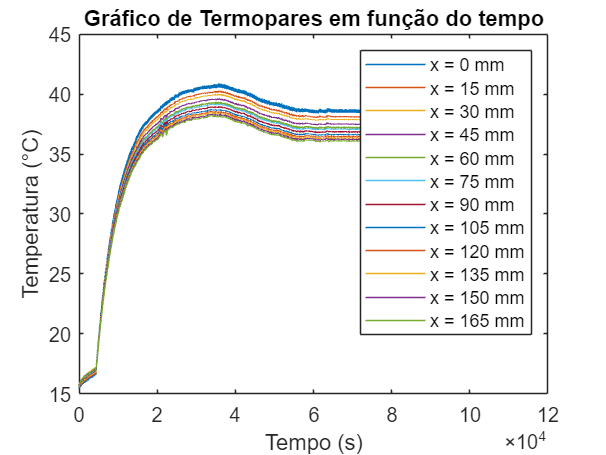

% Gráfico 0.1
time = data.x101Time_Sec_;
tamanho_time = length(time);
vetor_time = 10 * (0:tamanho_time-1);
termopares = {data.x102__C_, data.x103__C_, data.x104__C_, data.x105__C_, data.x106__C_, data.x107__C_, data.x108__C_, data.x109__C_, data.x110__C_, data.x111__C_, data.x112__C_, data.x113__C_};
legendas = {'x = 0 mm', 'x = 15 mm', 'x = 30 mm', 'x = 45 mm', 'x = 60 mm', 'x = 75 mm', 'x = 90 mm', 'x = 105 mm', 'x = 120 mm', 'x = 135 mm', 'x = 150 mm', 'x = 165 mm'};

for i = 1:length(termopares)
    plot(vetor_time, termopares{i});  
    hold on;  
end

hold off;  
legend(legendas);
xlabel('Tempo (s)');
ylabel('Temperatura (°C)');
title('Gráfico de Termopares em função do tempo');

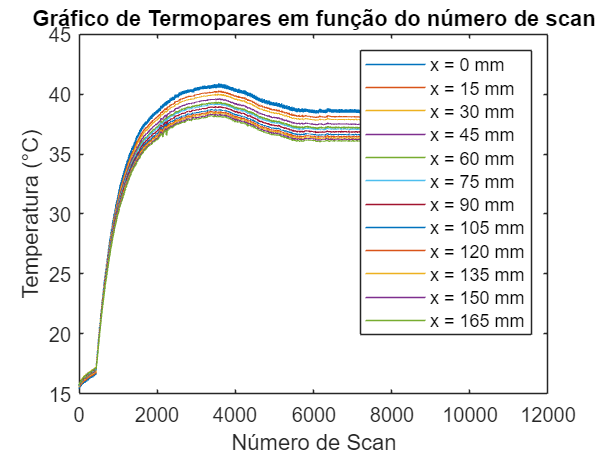

% Gráfico 0.2
vetor_num_scan = data.ScanNumber;
termopares = {data.x102__C_, data.x103__C_, data.x104__C_, data.x105__C_, data.x106__C_, data.x107__C_, data.x108__C_, data.x109__C_, data.x110__C_, data.x111__C_, data.x112__C_, data.x113__C_};
legendas = {'x = 0 mm', 'x = 15 mm', 'x = 30 mm', 'x = 45 mm', 'x = 60 mm', 'x = 75 mm', 'x = 90 mm', 'x = 105 mm', 'x = 120 mm', 'x = 135 mm', 'x = 150 mm', 'x = 165 mm'};

for i = 1:length(termopares)
    plot(vetor_num_scan, termopares{i});  
    hold on;  
end

hold off;  
legend(legendas);
xlabel('Número de Scan');
ylabel('Temperatura (°C)');
title('Gráfico de Termopares em função do número de scan');

#### Intervalo do regime permanente identificado: Scan 6000 a 8000

% Filtrar as linhas que compõem o intervalo de regime permanente
regime_permanente = data((data.ScanNumber >= 6000) & (data.ScanNumber <= 8000), :);

% Selecionar as temperaturas não-NaN no intervalo filtrado
ind = ~isnan(regime_permanente.x101__C_);
Tamb_col = regime_permanente.x101__C_(ind);

% Calcular a temperatura média ambiente no intervalo
Tmamb = mean(Tamb_col);

% Calculando a temperatura média na aleta no regime permanente
Tm_aleta = 0;
termopares = {regime_permanente.x102__C_, regime_permanente.x103__C_, regime_permanente.x104__C_, regime_permanente.x105__C_, regime_permanente.x106__C_, regime_permanente.x107__C_, regime_permanente.x108__C_, regime_permanente.x109__C_, regime_permanente.x110__C_, regime_permanente.x111__C_, regime_permanente.x112__C_, regime_permanente.x113__C_};
Tm_x = zeros(1,12);

for i = 1: length(termopares)
    Tm_x(i) = mean(termopares{i});   % Media de cada 
    % posicao da aleta, durante reg perm
    Tm_aleta = Tm_aleta + mean(termopares{i});
end

Tm_aleta = Tm_aleta/12;

% Temperatura de filme
Tf = (Tm_aleta + Tmamb)/2;

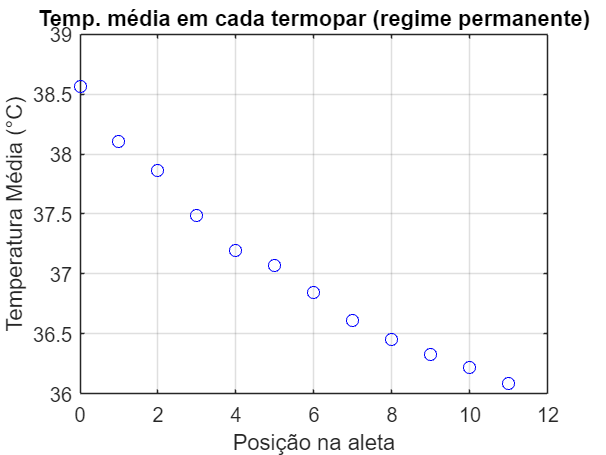

% Gráfico 1
posicoes = zeros(1,12);
init = 16;
for i = 1:length(Tm_x)
    posicoes(i) = i - 1;
end

plot(posicoes, Tm_x, 'ob');
title("Gráfico 1");
xlabel('Posição na aleta');
ylabel('Temperatura Média (°C)');
grid on;
title('Temp. média em cada termopar (regime permanente)');

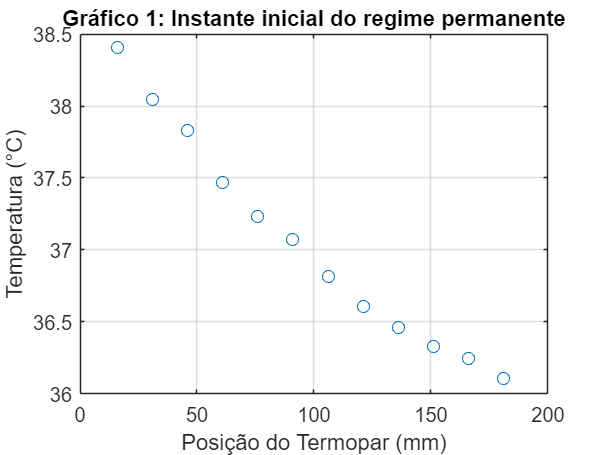

% Gráfico 1: Utilizando o instante de início do regime permanente para o gráfico 1
temperaturas_inicio_regime = data(data.ScanNumber == 6000, :);
termopares_posicao = 16:15:181;
valores_termopares = zeros(1, 12);

for i = 102:113
    col_name = sprintf('x%d__C_', i); 
    valores_termopares(i - 101) = temperaturas_inicio_regime.(col_name);
end

plot(termopares_posicao, valores_termopares, 'o');  
title("Gráfico 1: Instante inicial do regime permanente");
xlabel('Posição do Termopar (mm)');
ylabel('Temperatura (°C)');
grid on;

% Calculando a condutividade do material no regime permanente (k), usando:
x0 = 37.78;
f_x0 = 155.68;

x1 = 51.67;
f_x1 = 156.88;

% Interpolacao de Newton:
%      f1(x) = f(x0) + (( f(x1) - f(x0) )   /  ( x1 - x0 )) * ( x - x0 )
k_Tf = f_x0 + ( ( f_x1 - f_x0 ) / (x1 - x0)) * (Tf - x0)

k_Tf = 154.7479

% Grafico 2: Modelo Analitico
r = 0.012

r = 0.0120

Atr = pi*r^2

Atr = 4.5239e-04

L = 0.2

L = 0.2000

Tb = Tm_x(1)

Tb = 38.5648

Tamb = 16

Tamb = 16

h = 5.5 % Slide Aula 6

h = 5.5000

P = 2*pi*r

P = 0.0754

m = sqrt((h*P)/(k_Tf*Atr))

m = 2.4338

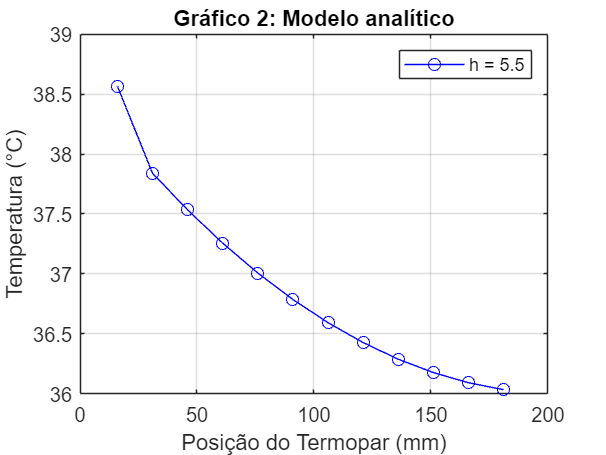


valores_termopares_analitico_1 = zeros(size(Tm_x));

for i = 1:length(termopares_posicao)
    position = termopares_posicao(i);
    if i == 1
        valores_termopares_analitico_1(i) = Tm_x(i);
    else
        valores_termopares_analitico_1(i) = (Tb-Tamb)*((cosh(m*(L - (position/1000))) +  (h/(m*k_Tf))*sinh(m*(L - (position/1000))))/(cosh(m*L) + (h/(m*k_Tf))*sinh(m*L))) + Tamb;
    end
end

plot(termopares_posicao, valores_termopares_analitico_1, "-ob");
title("Gráfico 2: Modelo analítico");
xlabel('Posição do Termopar (mm)');
ylabel('Temperatura (°C)');
legend({'h = 5.5'});
grid on;

% Grafico 2: Modelo Analitico
r = 0.012

r = 0.0120

Atr = pi*r^2

Atr = 4.5239e-04

L = 0.2

L = 0.2000

Tb = Tm_x(1)

Tb = 38.5648

Tamb = 16

Tamb = 16

h = 5.5 % Slide Aula 6

h = 5.5000

P = 2*pi*r

P = 0.0754

m = sqrt((h*P)/(k_Tf*Atr))

m = 2.4338

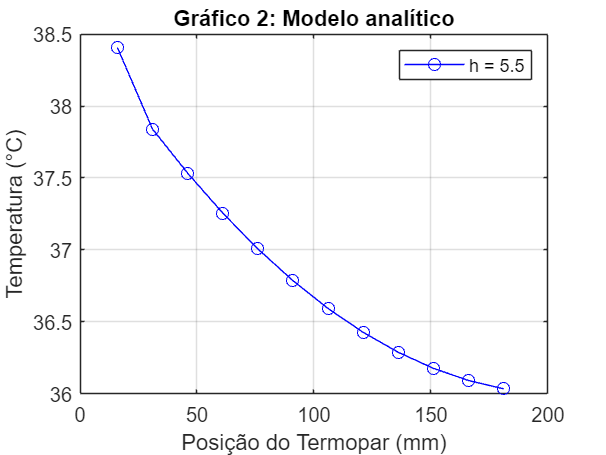


valores_termopares_analitico = zeros(size(termopares_posicao));

for i = 1:length(termopares_posicao)
    position = termopares_posicao(i);
    if i == 1
        valores_termopares_analitico(i) = valores_termopares(i);
    else
        valores_termopares_analitico(i) = (Tb-Tamb)*((cosh(m*(L - (position/1000))) +  (h/(m*k_Tf))*sinh(m*(L - (position/1000))))/(cosh(m*L) + (h/(m*k_Tf))*sinh(m*L))) + Tamb;
    end
end

plot(termopares_posicao, valores_termopares_analitico, "-ob");
title("Gráfico 2: Modelo analítico");
xlabel('Posição do Termopar (mm)');
ylabel('Temperatura (°C)');
legend({'h = 5.5'});
grid on;

% Grafico 3: Modelo Numerico (Antonio)
rho = 2794;
c = 880;
%alpha = k_Tf/(rho*c);

deltaT = 0.1;
deltaX = 0.15;

valores_termopar_numerico = zeros(1, 12);

for i = 102:113
    As = Atr*deltaX;
    m = i - 101
    if m == 12
        qcond_out = 0;
    else
        qcond_out = k_Tf*Atr*(Tm_x(m) - Tm_x(m+1))/(deltaX);
    end

    if m == 1
        qcond_in = k_Tf*Atr*(Tb - Tm_x(m))/(deltaX);
    else
        qcond_in = k_Tf*Atr*(Tm_x(m-1) - Tm_x(m))/(deltaX);
    end

    qconv = h*As*(Tm_x(m) - Tb);

    if m == 1
        valores_termopar_numerico(m) = Tm_x(m)
    else
        valores_termopar_numerico(m) = Tm_x(m) + deltaT/(rho*Atr*deltaX*c) * (qcond_in - qcond_out - qconv);
    end
end

m = 1

valores_termopar_numerico =    38.5648         0         0         0         0         0         0         0         0         0         0         0


m = 2

m = 3

m = 4

m = 5

m = 6

m = 7

m = 8

m = 9

m = 10

m = 11

m = 12

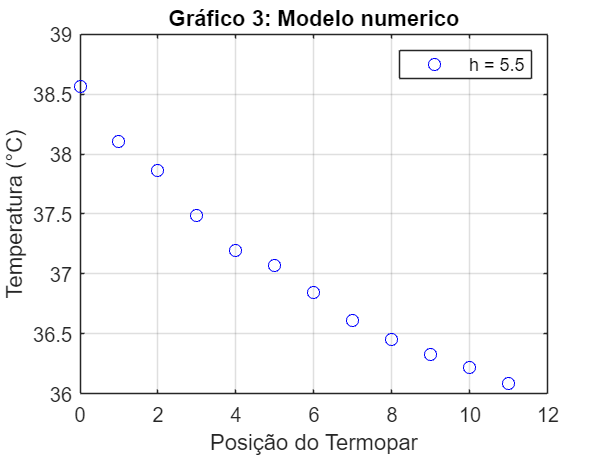


plot(posicoes, valores_termopar_numerico, "ob");
title("Gráfico 3: Modelo numerico");
xlabel('Posição do Termopar');
ylabel('Temperatura (°C)');
legend({'h = 5.5'});
grid on;

% Gráfico 3: Modelo numérico (Nery)
deltat = 10 % s

deltat = 10

deltax = 15/1000 % m

deltax = 0.0150

erro_max = 0

erro_max = 0

rho = 2794 % kg/m^3

rho = 2794

c = 880 % J/kg*K

c = 880

alpha = k_Tf/(rho*c)

alpha = 6.2938e-05

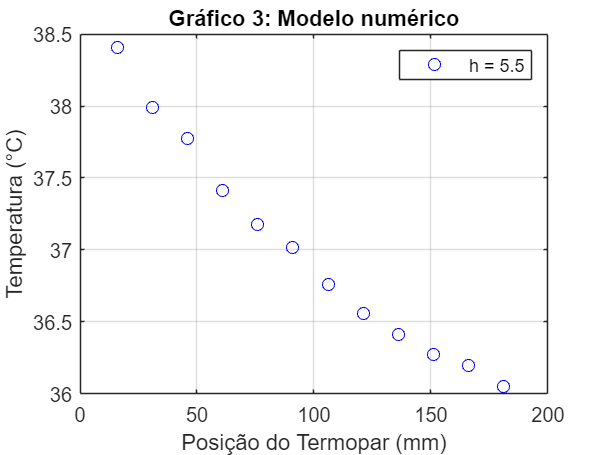

temp_vetor = zeros(1,12);

for i = 102:113
    anterior = sprintf('x%d__C_', i-1);
    atual = sprintf('x%d__C_', i);
    proximo = sprintf('x%d__C_', i+1);
    if i == 113 % Último nó não tem condução de saída do vizinho direito
        cond_entrada = (temperaturas_inicio_regime.(anterior) - temperaturas_inicio_regime.(atual))/deltax;
        conv_saida = h*Atr*(temperaturas_inicio_regime.(atual) - Tamb);
        temp = alpha*deltat*(Atr*(cond_entrada)) - conv_saida + temperaturas_inicio_regime.(atual);
    elseif  i == 102
        temp = valores_termopares(i - 101);
    else
        cond_entrada = (temperaturas_inicio_regime.(anterior) - temperaturas_inicio_regime.(atual))/deltax;
        cond_saida = (temperaturas_inicio_regime.(proximo) - temperaturas_inicio_regime.(atual))/deltax;
        conv_saida = h*Atr*(temperaturas_inicio_regime.(atual) - Tamb);
        temp = alpha*deltat*(Atr*((cond_entrada) - (cond_saida))) - conv_saida + temperaturas_inicio_regime.(atual);
    end
    temp_vetor(i - 101) = temp;
    plot(termopares_posicao(i - 101), temp, "ob");
    hold on;
end

hold off;
title("Gráfico 3: Modelo numérico");
xlabel('Posição do Termopar (mm)');
ylabel('Temperatura (°C)');
legend({'h = 5.5'});
grid on;

% Gráfico 4: Comparacao Modelos (Antonio)
graf4_y_axis = [Tm_x; valores_termopares_analitico_1; valores_termopar_numerico];
cores = [0.8 0 0; 0 0 1; 0 0.5 0.]; % Red, Green, Blue
plot_line = ["o"; "-"; "s"];

for i = 1:size(graf4_y_axis, 1)
    majaaaaj = graf4_y_axis(i, 5)ç
    plot(posicoes, graf4_y_axis(i, :), plot_line(i,:), "Color", cores(i,:));
    hold on;
end

majaaaaj = 37.1976

majaaaaj = 37.0075

majaaaaj = 37.1977

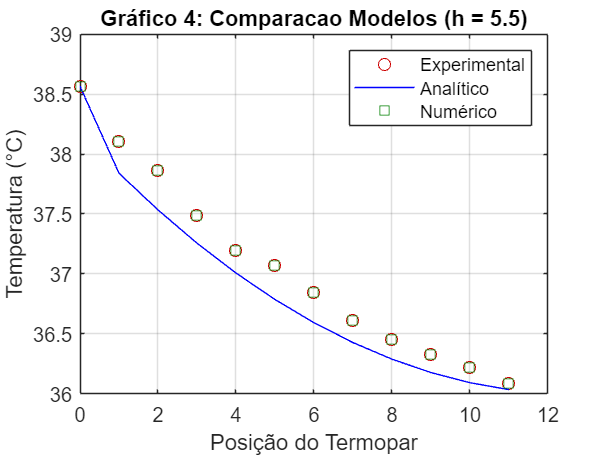


hold off;
title("Gráfico 4: Comparacao Modelos (h = 5.5)");
xlabel('Posição do Termopar');
ylabel('Temperatura (°C)');
legend({'Experimental', 'Analítico', 'Numérico'});
grid on;

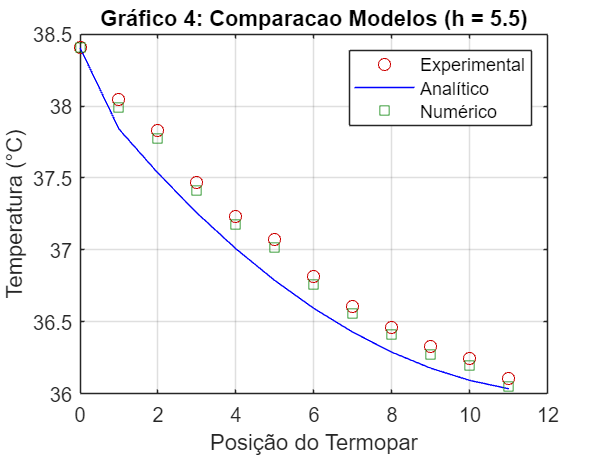

% Gráfico 4: Comparacao Modelos (Nery)
graf4_y_axis = [valores_termopares; valores_termopares_analitico; temp_vetor];
cores = [0.8 0 0; 0 0 1; 0 0.5 0.]; % Red, Green, Blue
plot_line = ["o"; "-"; "s"];

for i = 1:size(graf4_y_axis, 1)
    plot(posicoes, graf4_y_axis(i, :), plot_line(i,:), "Color", cores(i,:));
    hold on;
end

hold off;
title("Gráfico 4: Comparacao Modelos (h = 5.5)");
xlabel('Posição do Termopar');
ylabel('Temperatura (°C)');
legend({'Experimental', 'Analítico', 'Numérico'});
grid on;